# Example 1: Getting Started

This example shows how to get a simple Simulink model running on the drone in external mode. The model will verify whether the firmware on your drone is supported.

## Setting up the WIFI connection

The AR Drone 2.0 creates it's own WIFI network on startup called 'ardrone2'. Connecting a PC to this unsecured network allows the uploading of code to the drone. By default the AR Drone 2.0 will give itself the IP Adress '192.168.1.1' and the PC will have '192.168.1.2'.

## The first Simulink model

The AR Drone 2.0 Hardware support package has been developed using multiple drones running on firmware version 2.4.8. In order to make sure that your drone is compatible with the AR Drone 2.0 Hardware support package the first model will consist of nothing more than a block which checks if the AR Drone is running this supported firmware version and then outputs that to a display. Open the model by executing the following command in your MATLAB workspace:

open('Example1_Getting_Started')

The model should now open and appear as below:

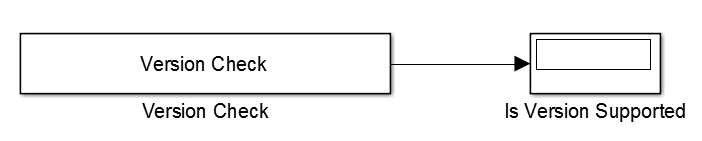

The Version Check block is created using the MATLAB Legacy Code Tool which can be used to integrate legacy C code into Simulink. If you wish to see what the underlying C code contains, execute the following MATLAB command in the workspace:

edit('versionCheck.c')

This C file contains three functions, versionCheckInit is called at when the model begins execution, in this case it reads the version.txt file which is by default located in the update folder on the AR Drone 2.0. The code then compares the found version with the known supported version, if they differ the static internal variable isSupported is set from 1 (supported) to 0 (not supported). The second function, versionCheckStep, is called during every execution step on the AR Drone. It sets the output of the Simulink block equal to the internal isSupported variable allowing us to see the result of the initialization function. The last function is the versionCheckClose function which is called when the model terminates. It is included for completeness of the implementation but as no memory is allocated no cleanup is necessary and the close function is kept empty.

The Simulink model is allready configured to run on the AR Drone 2.0 using external mode. Openening the Configuration Parameters can be done by pressing the   button in Simulink or by pressing 'ctrl + E'. This will bring you to a Configuration Reference window where the specific Configuration can be selected. For this example we will run the model in external mode allowing us to send commands and retrieve data from the drone while the model runs on the drone which is why the 'AR_Drone_ConfigSet' is selected, another configset could be set 'AR_Drone_ConfigSet_NOEXT' if it is desired to run the model in normal mode. Without the use of external mode the model will still run on the drone however we would be unable to see the "Is Version Supported" display output. 

## Running custom firmware verification code on the AR Drone 2.0

Make sure the model is set to external mode and then build the model using the   button or pressing 'ctrl + B'. The configuration set by default has the 'Build load and run' option selected meaning the software will be automatically transfered to the drone over FTP and made ready for a connection with Simulink. Once the process is complete a console window will popup with the text '**starting the model**' and some codes relevant to the motor initialization. At this point click 'Connect to target'   in Simulink  which will transfer any parameters that are tunable in real time (in this case the desired LED color). Once this is done the 'Run'   button will turn green, press it to start the model on the drone. The "Is Version Supported" display will now display a value of either "0" (your drone does not run a supported firmware version) or "1" (your drones software version is supported). If the display shows "0" this does not necessarily mean that your drone is incompatible with this Hardware support package but care should be taken when using the provided models as they are untested for your drones firmware version.

When you are done with this example you can stop it's execution using the 'Stop'   button in Simulink. Without having to reboot the drone you can run any desired model on the drone by following the steps above again.